### Demo

clear % Add repository folders to path
mfilePath = mfilename('fullpath');
if contains(mfilePath,'LiveEditorEvaluationHelper')
    mfilePath = matlab.desktop.editor.getActiveFilename;
end
folder_path = strsplit(mfilePath,filesep);
repo_path = join([folder_path(1:end-2)],filesep);
repo_path = repo_path{1};
data_path = [repo_path,filesep,'data'];
src_path = [repo_path,filesep,'src'];
tenandet_path = [repo_path,filesep,'tenandet'];
testbench_path = [repo_path,filesep,'testbench'];
addpath(genpath(data_path), genpath(src_path),genpath(tenandet_path), genpath(testbench_path));
clear folder_path mfilePath repo_path data_path testbench_path src_path tenandet_path

### Load NYC data

sizes = [144,7,52,10];                                      % Load NYC data 
load nyc_tensors.mat
load regions.mat
arrs = squeeze(sum(reshape(arrs,6,24,365,[]),1)); 
Y = double(reshape(arrs(:,1:364,regions), 24, 7, 52,[]));   % Select 81 zones
Y(:,1,53,:) = arrs(:,365,regions);
Y(:,2:7,53,:) = mean(Y(:,2:7,1:52,:),3);                    % Fill in the last week with the mean of other weeks

[mgen,X,Xgen,rmd,manomaly] = gendata(size(Y),0,10,5,Y);

**See the singular value distributions of the arrivals in different modes:**

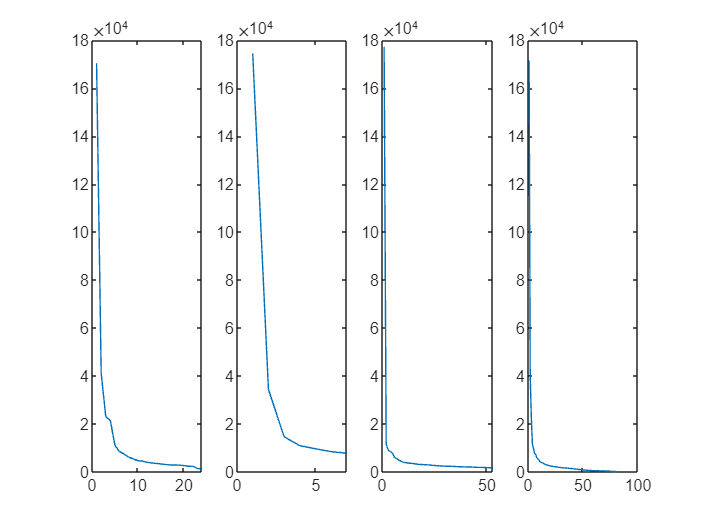

s1 = svd(t2m(Y,1));
s2 = svd(t2m(Y,2));
s3 = svd(t2m(Y,3));
s4 = svd(t2m(Y,4));
figure;
subplot(141)
plot(s1)
subplot(142)
plot(s2)
subplot(143)
plot(s3)
subplot(144)
plot(s4)

**Add Anomalies:**

select_loc = [5,40];
sz = size(Y);
Anomaly_mask = zeros(sz);
a = zeros([sz(1:3),5]);
[a, anomaly_mask] = add_persistent_anomaly(Y(:,:,:,select_loc),8,300,2.5,1);
Yn = Y;
Yn(:,:,:,select_loc) = Y(:,:,:,select_loc) + a;
Anomaly_mask(:,:,:,select_loc) = anomaly_mask;

### Visualize NYC Data:

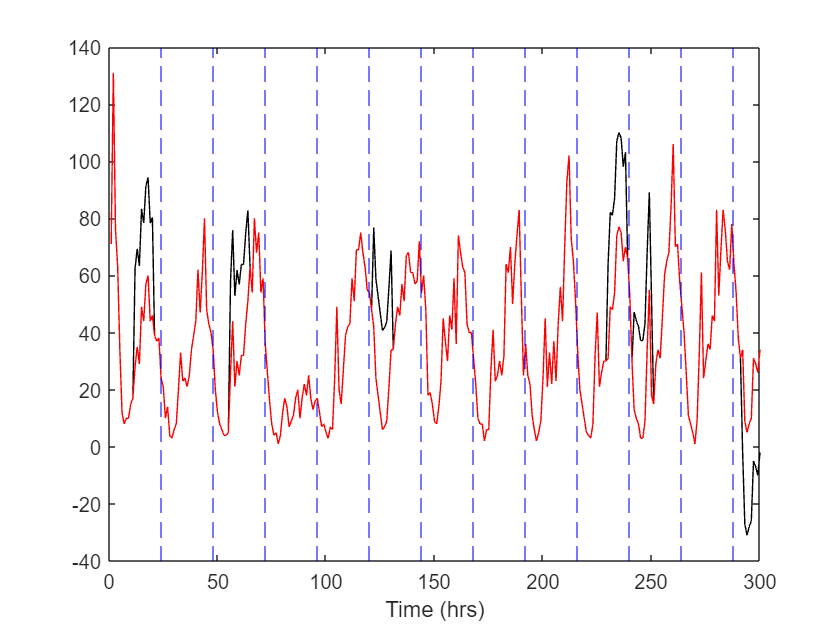

window_length=300;
locations = [5,40];
day_count = floor(window_length/24);
figure;
yn = t2m(Yn,4);
y = t2m(Y,4);
t = [1:window_length]; days = [1:day_count]*24;
plot(t,yn(5,1:window_length),'k')
hold on;
plot(t,y(5,1:window_length),'r')
xlabel("Time (hrs)")
xline(days,'--b')

param = set_params(Yn);
param.lambda=5e-2;
param.gamma=5e-2;
param.err_tol=1e-6;
%param.psi = [1,1,1,1];
param.max_iter=400;
tic
[L,S,~,~]= loss(Yn, param);

Max iter


toc

Elapsed time is 316.453681 seconds.


norm(Y-L-S,'fro')/norm(Y,'fro')

ans = 0.0367

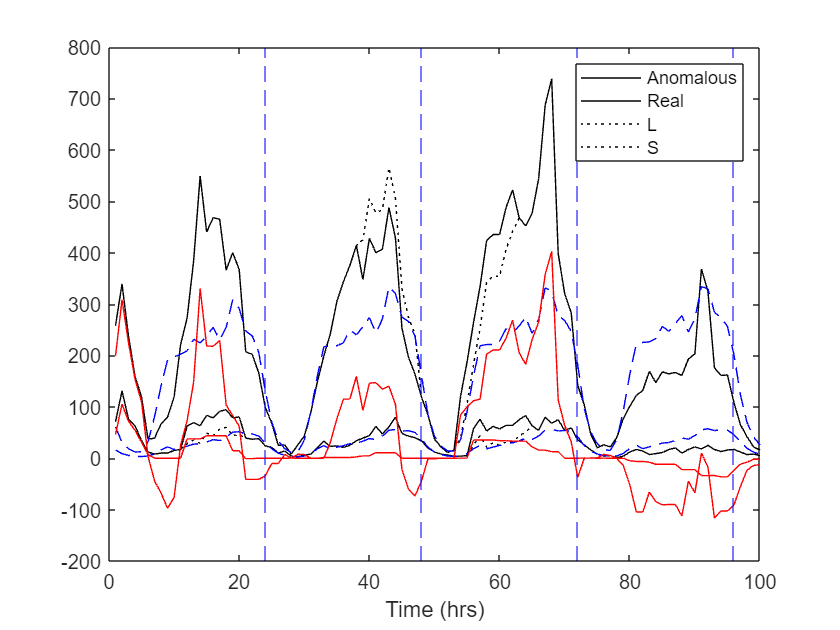

locations = [5,40];
window_length=100;
day_count = floor(window_length/24);
t = [1:window_length]; days = [1:day_count]*24;
s= t2m(S,4);
l= t2m(L,4);

f1=figure;
clear f1
f1 = figure;
plot(t,yn(locations,1:window_length),'black')
hold on
plot(t,y(locations,1:window_length),':black')
plot(t,l(locations,1:window_length),'--blue')
plot(t,s(locations,1:window_length),'red')
xlabel("Time (hrs)")
xline(days,'--b')
legend('Anomalous', 'Real', 'L','S');

### Outlying score for each location

Sn = cell(81,1);
outlying_score = zeros(81,1);
for n =1:81
    Sn{n}= squeeze(S(:,:,:,n));
end

Unrecognized function or variable 'S'.

tic
for n=1:81
    z = Sn{n};
    % outlying_score(n) 
    [OS, Or]= outlying_function2(z,Sn,250,1e-4,0);
    outlying_score(n)= OS;
    if mod(n,18)==0
        n
    end
end
toc

%labels = cell(81,1);
labels= {'Normal'};
labels =repmat(labels,81,1);
labels{5} = 'Anomaly'; labels{40} = 'Anomaly';
classNames = cell(2,1);
classNames{1}='Normal';
classNames{2}='Anomaly';
score = [-outlying_score,outlying_score];
rocObj = rocmetrics(labels,score,classNames);

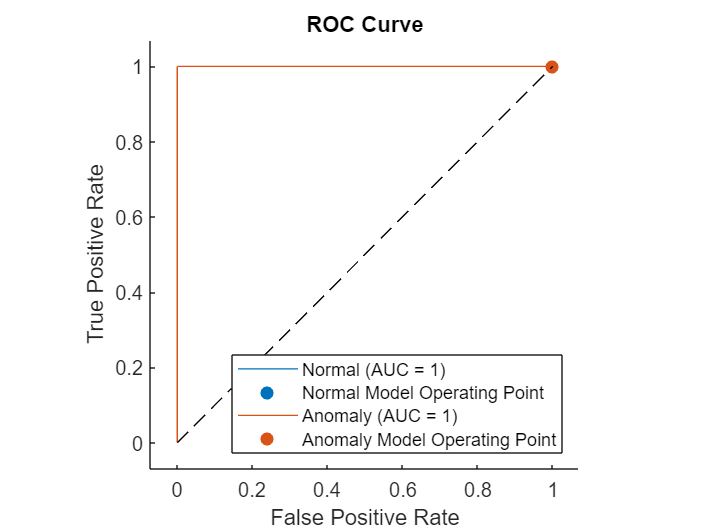

plot(rocObj)

Outlying functions run for a single sample plotted.

Sn = cell(81,1);
outlying_score = zeros(81,1);

i = [1:3]; j =[1:3];
lambda = 5e-4; gamma = 5e-6;
O1 = zeros(3,3,81);
O2 = zeros(3,3,81);
for i =1:3
for j =1:3
    tic
    param.lambda=lambda*i;
    param.gamma=gamma*j;
    
    [L,S,~,~]= loss(Y, param);
    for n =1:81
        Sn{n}= squeeze(S(:,:,:,n));
    end
    for n=1:81
        z = Sn{n};
        O1(i,j,n) = outlying_function(z,Sn,100,20);
        O2(i,j,n) = outlying_function2(z,Sn,40,1e-3,0);
        if mod(n,18)==0
            n
        end
    end
    toc
end
end

Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 282.388555 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 331.093733 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 267.792359 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 227.894470 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 239.266106 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 228.555300 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 226.928342 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 229.402054 seconds.


Max iter


n = 18

n = 36

n = 54

n = 72

Elapsed time is 227.776183 seconds.


###  Generate synthetic data with synthetic anomalies

**Parameters:**

- `number_anomaly`: Number of anomalous points

- `length_anomaly` : Anomaly length

- `amplitude_anomaly`: Amplitude of the anomaly

**Variables:**

- `Y_gen`: Simulated ground truth

- `Yn`: Simulated anomalous data

- `M`: Mask tensor. 1's indicate the anomalous entries

sizes = [24,7,53,81];   
number_anomaly = 1;
length_anomaly = 23;
amplitude_anomaly = 8;
[M, Y_gen, Yn, ind_removed, mat_anom] =gendata(sizes, number_anomaly, length_anomaly, amplitude_anomaly, Y, 0);
m= t2m(M,4); 
y= t2m(Y_gen,4);
z= t2m(Yn,4);

### Example plot:

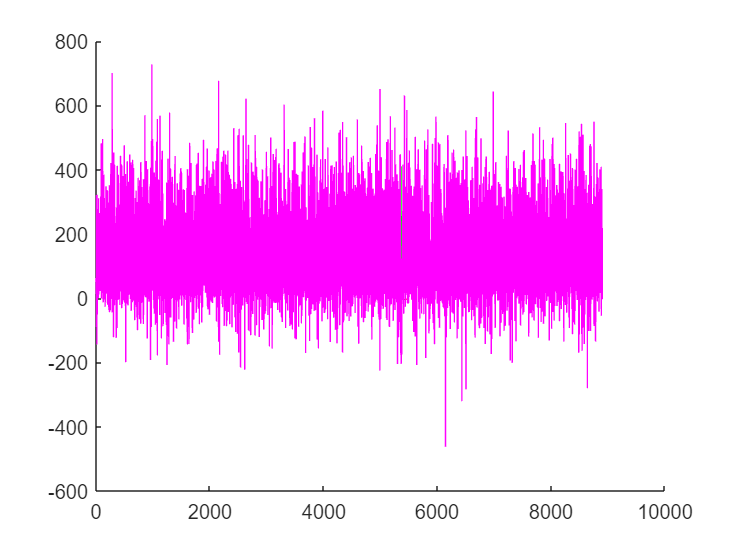

t= [1:8900];
loc = 15;
figure;
scatter(t(mod(1:96,8900)==0),0,'bx')
hold on;
scatter(t(m(loc,1:8900)==1),0,'r+')
hold on
plot(y(loc,1:8900),'g')
plot(z(loc,1:8900),'m')

### Example implementation of LOSS Function:

Parameters follow Dr. Aviyente and Emres' GLOSS paper.

param = set_params(Yn);
param.beta_1=1;
param.beta_2=1;
param.beta_3=1;
param.beta_4=1;
param.beta_5=1;
param.lambda=1e-6;
% param.gamma=1/81;
% param.psi=1;
% param.alpha=0;
param.err_tol=1e-3;
param.max_iter=500;
param.ind_m =ind_removed;
tic
[L,S,Nt,times]= loss(Yn, param);

Max iter


toc

Elapsed time is 98.873220 seconds.


#### Example Algorithm Result:

- `S: Smooth and Sparse part (plotted in black)`

- `L: Low-rank part          (plotted in blue)`

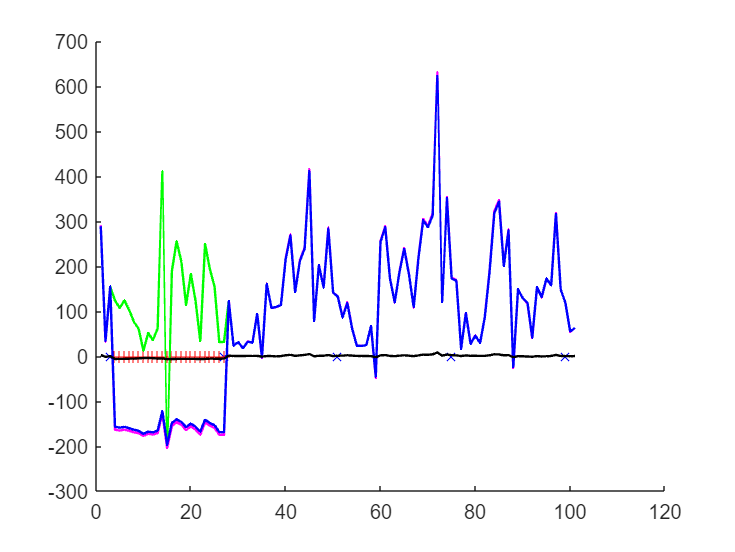

s= t2m(S,4);
l= t2m(L,4);
loc = 15;
figure;
scatter(t(mod(5350:5450,24)==0),0,'bx')
hold on;
scatter(t(m(loc,5350:5450)==1),0,'r+')
hold on
plot(y(loc,5350:5450),'g','LineWidth',1.2)
plot(z(loc,5350:5450),'m','LineWidth',1.2)
plot(l(loc,5350:5450),'blue','LineWidth',1.2)
plot(s(loc,5350:5450),'k','LineWidth',1.2)

norm(Yn-L-S,'fro')/norm(Yn,'fro')

ans = 5.9057e-05

Sn = cell(81,1);
outlying_score = zeros(81,1);
for n =1:81
    Sn{n}= squeeze(Yn(:,:,:,n));
end
z = Sn{5};
[O,Or] = outlying_function2(z,Sn,100,1e-3);

Converged


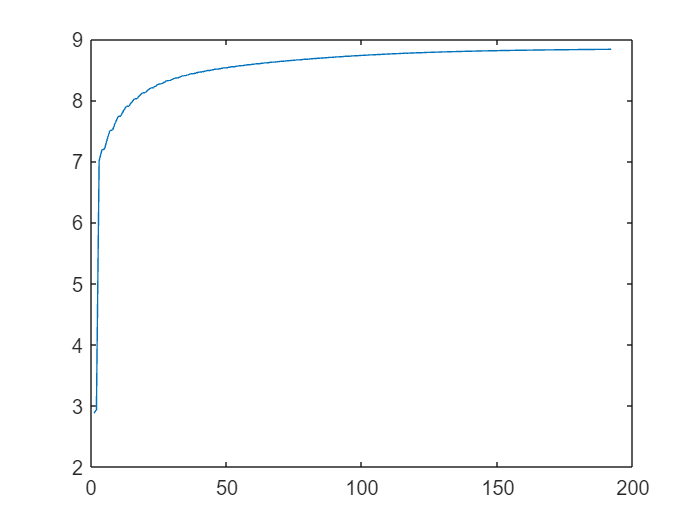

figure;
plot(Or)


for n=1:81
    z = Sn{n};
    outlying_score(n) = outlying_function2(z,Sn,100,1e-3);
    if mod(n,9)==0
        n
    end
end

Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 9

Converged
Converged
Converged
Converged


n = 18

Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 27

Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 36

Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 45

Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 54

Converged
Converged
Converged


n = 63

Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 72

Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged
Converged


n = 81

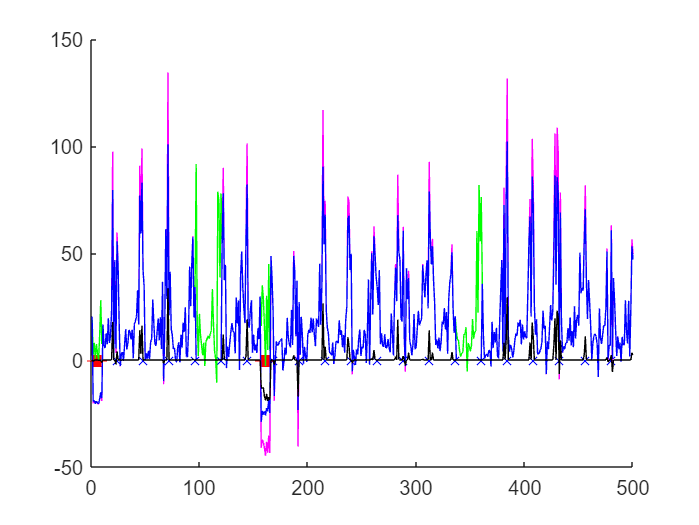


lw =0.5; plen =500; loc=58; t=[1:plen];
s= t2m(S,4);
l= t2m(L,4);
z= t2m(Yn,4);
loc = 28;
figure;
scatter(t(mod(1:plen,24)==0),0,'bx')
hold on;
scatter(t(m(loc,1:plen)==1),0,'r+')
hold on
plot(y(loc,1:plen),'g','LineWidth',lw)
plot(z(loc,1:plen),'m','LineWidth',lw)
plot(l(loc,1:plen),'blue','LineWidth',lw)
plot(s(loc,1:plen),'k','LineWidth',lw)